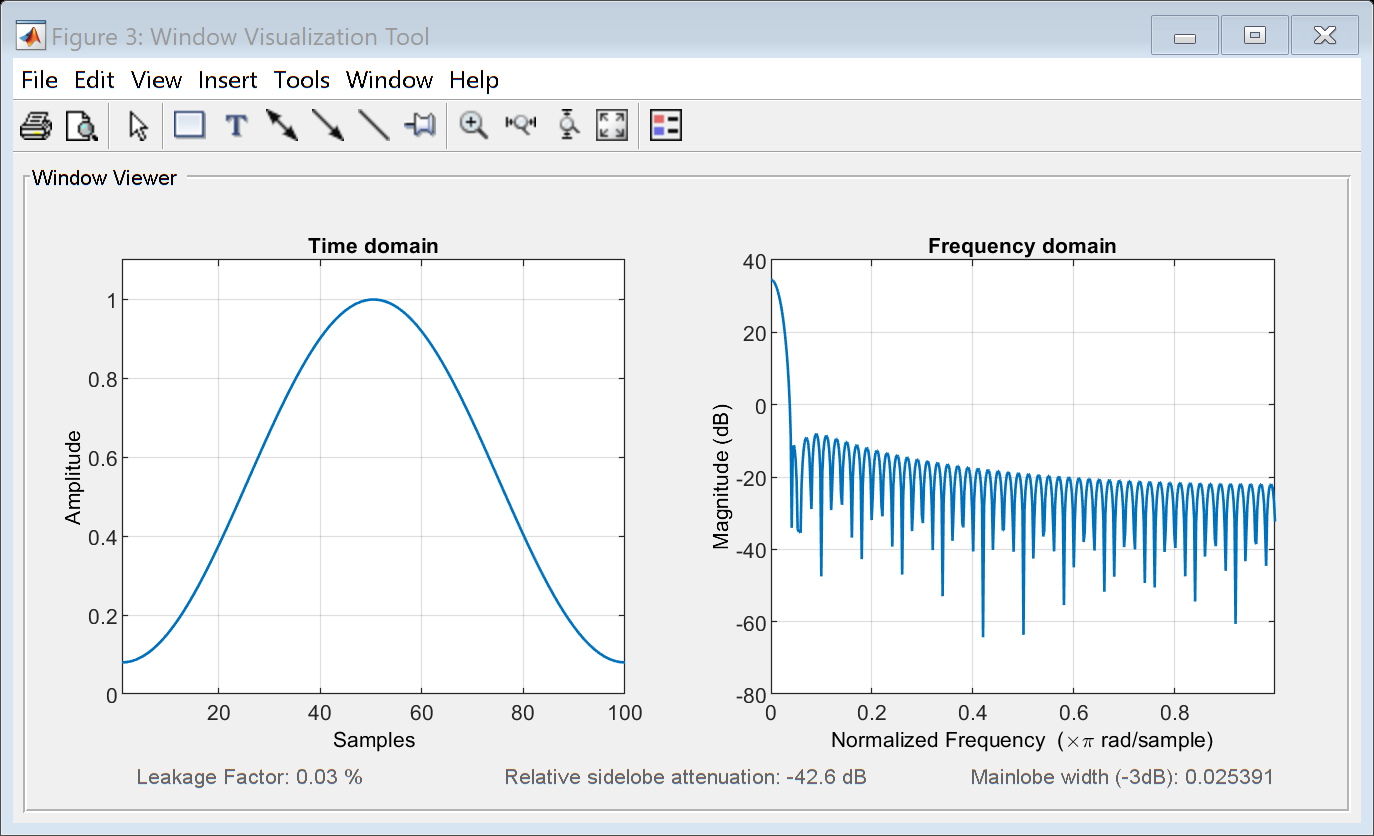

alpha = 1+mod(119,3);
L = 100;
wvtool(hamming(L))

title("hamming window")

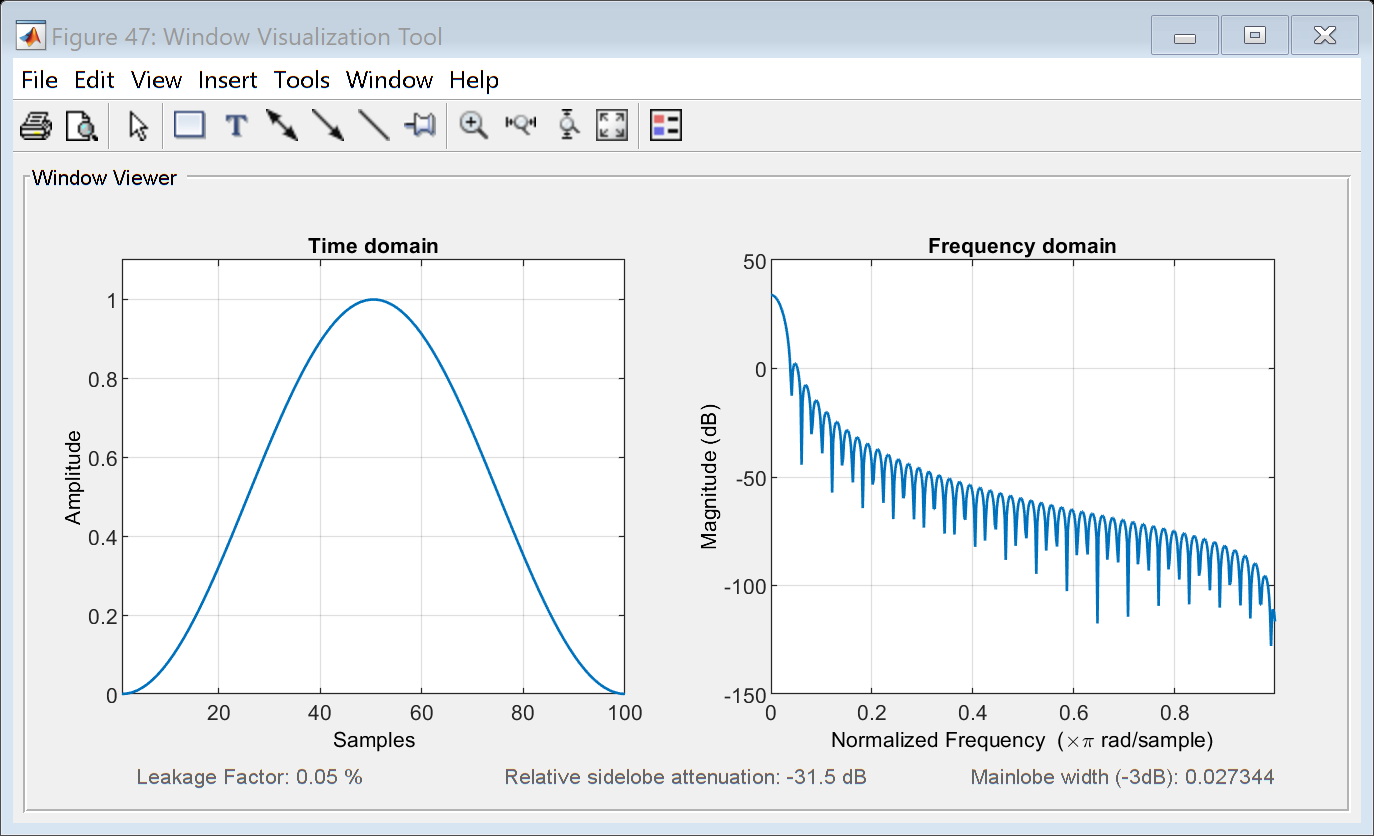

wvtool(hann(L))

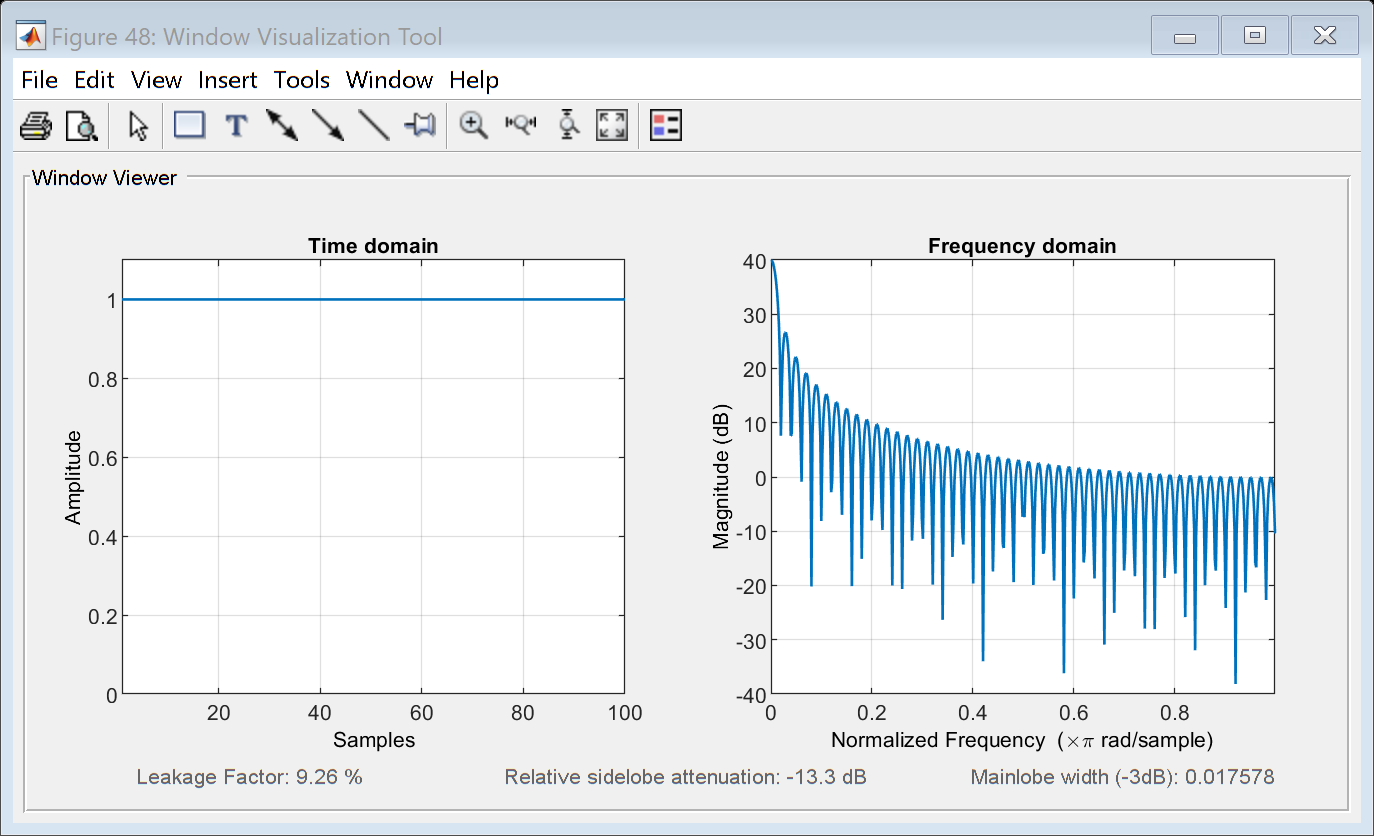

wvtool(rectwin(L))

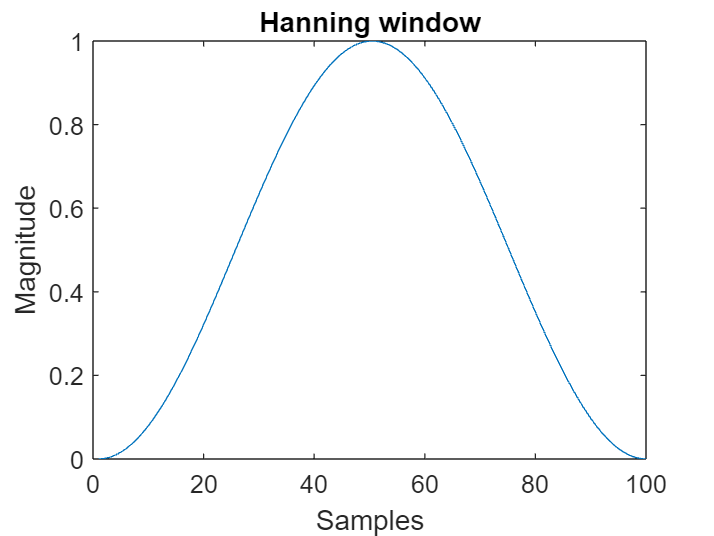

plot(hann(L))
xlabel("Samples")
ylabel("Magnitude")
title("Hanning window")

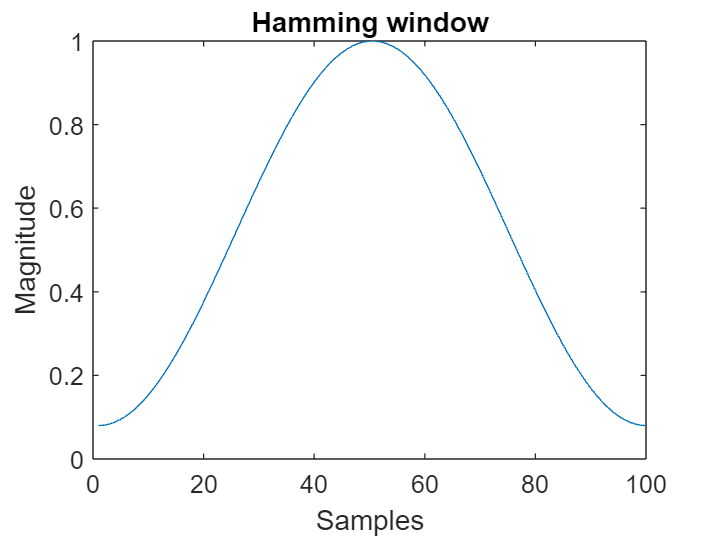

plot(hamming(L))
xlabel("Samples")
title("Hamming window")
ylabel("Magnitude")

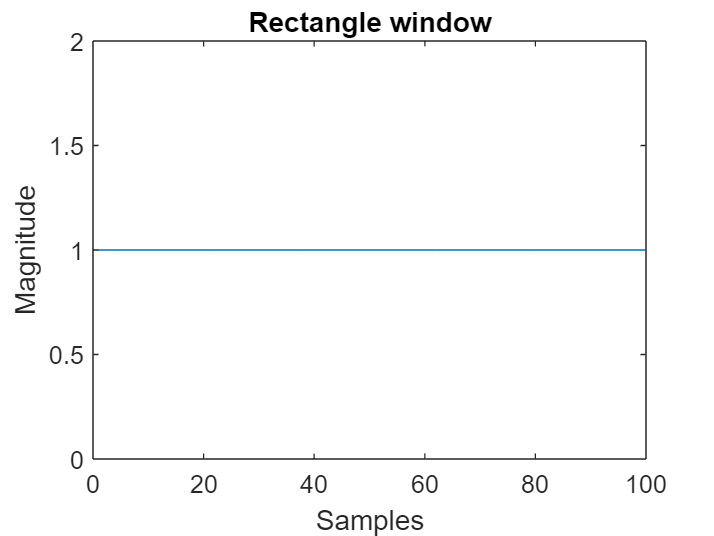

plot(rectwin(L))
xlabel("Samples")
ylabel("Magnitude")
title("Rectangle window")

N = 1024

N = 1024

N2 = 100

N2 = 100

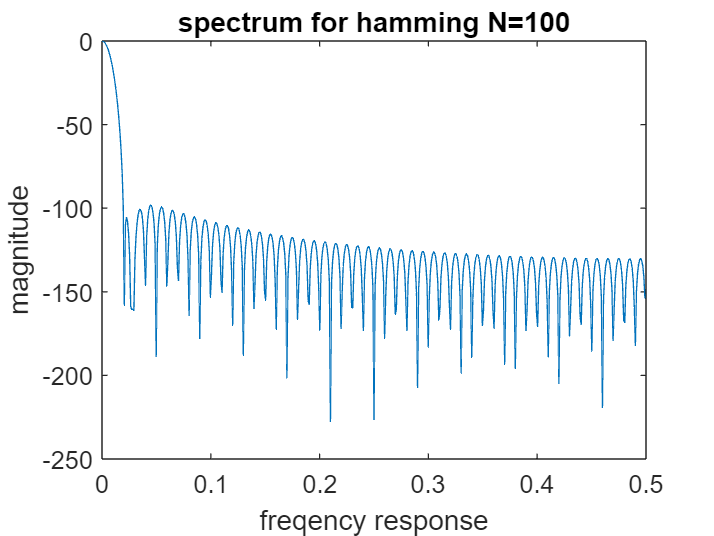

y = hamming(N2);
yf1 = abs((fft(y,N))/300);
f = (0:N/2-1)./N;
k = yf1(1:length(f))/max(yf1);
f1 = 20*log(k);
plot(f,f1);
xlabel("freqency response");
ylabel("magnitude")
title("spectrum for hamming N=100")

N2=200

N2 = 200

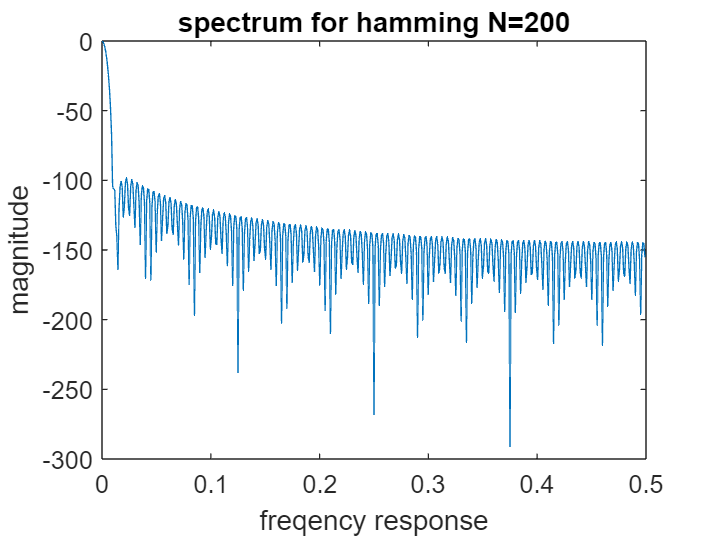

y = hamming(N2);
yf1 = abs((fft(y,N))/300);
f = (0:N/2-1)./N;
k = yf1(1:length(f))/max(yf1);
f1 = 20*log(k);
plot(f,f1);
xlabel("freqency response");
ylabel("magnitude")
title("spectrum for hamming N=200")

N2=300

N2 = 300

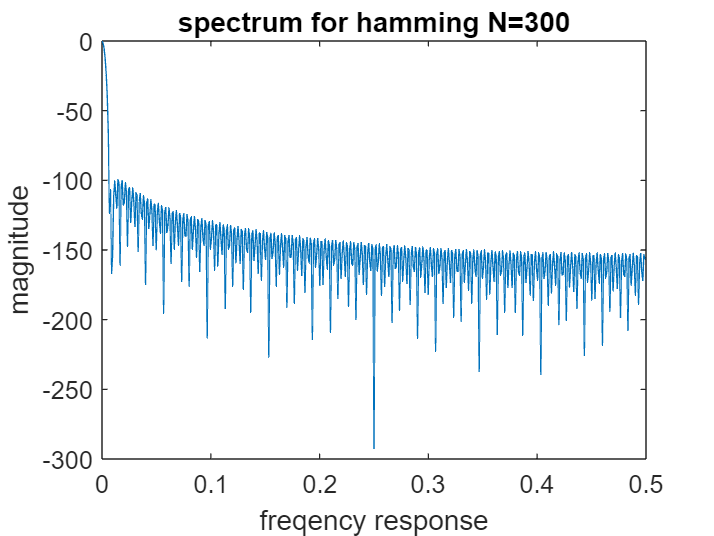

y = hamming(N2);
yf1 = abs((fft(y,N))/300);
f = (0:N/2-1)./N;
k = yf1(1:length(f))/max(yf1);
f1 = 20*log(k);
plot(f,f1);
xlabel("freqency response");
ylabel("magnitude")
title("spectrum for hamming N=300")

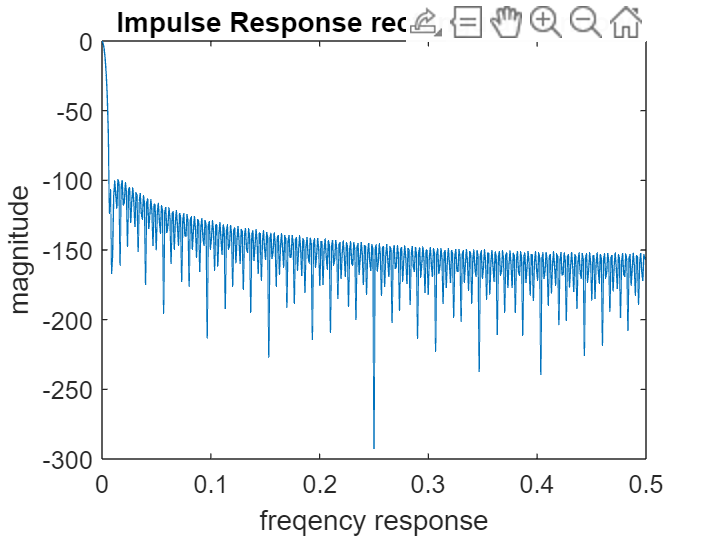

b = fir1(20,0.25,"low",rectwin(21));
title("Impulse Response rectangular window")

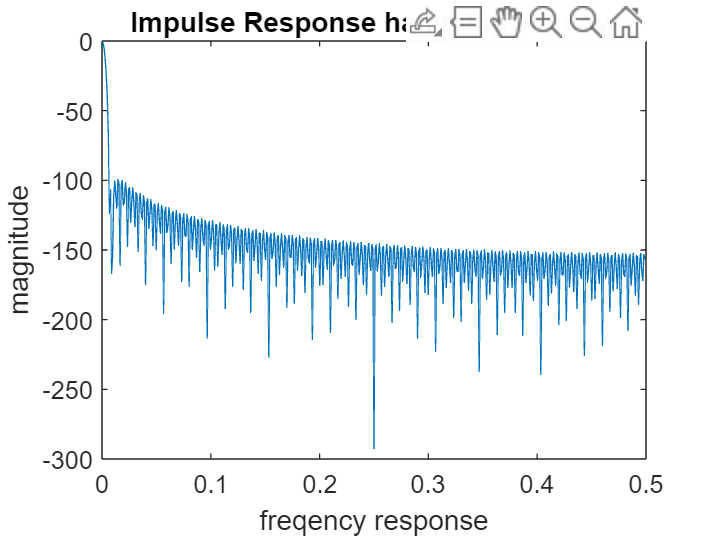

b1 = fir1(20,0.25,"low",hamming(21));
title("Impulse Response hamming window")

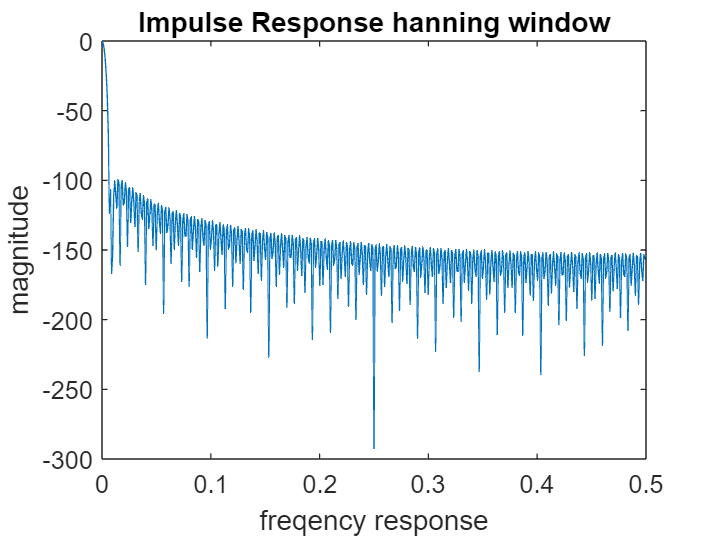

b2 = fir1(20,0.25,"low",hanning(21));
title("Impulse Response hanning window")

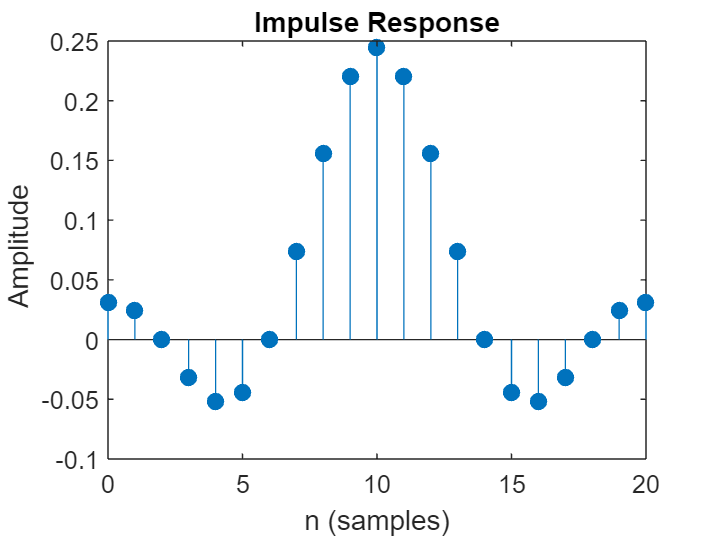

impz(b)

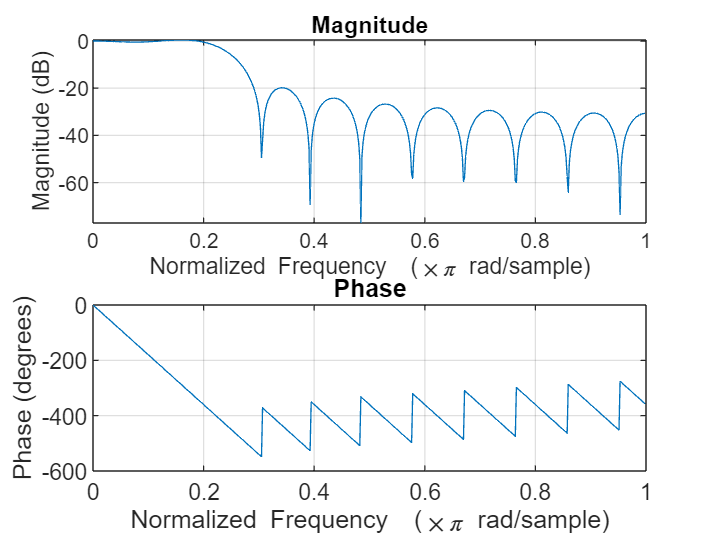

freqz(b);

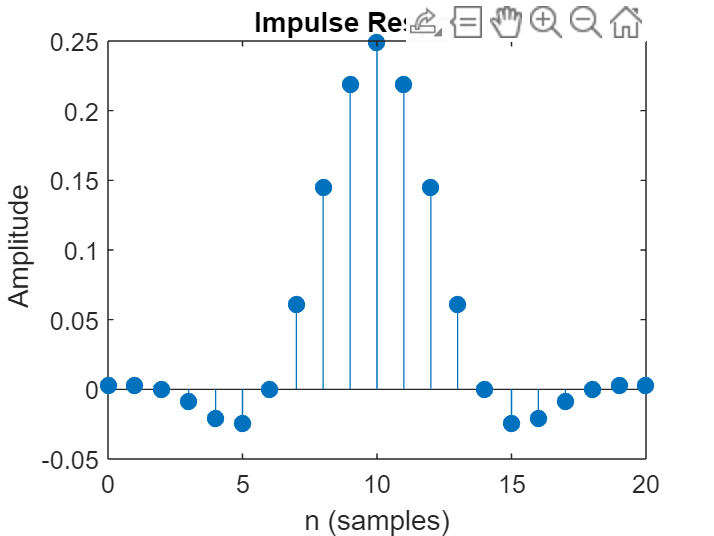

impz(b1);

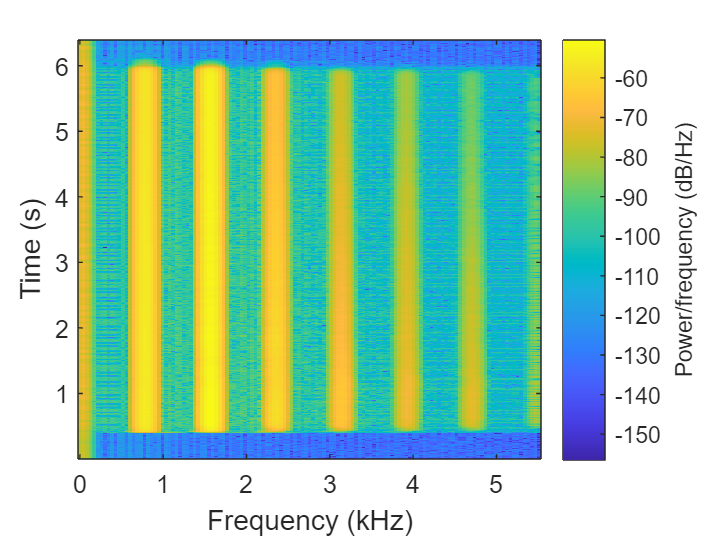

[y,fs] = audioread("instru3.wav");
spectrogram(y,hamming(100),10,256,fs)

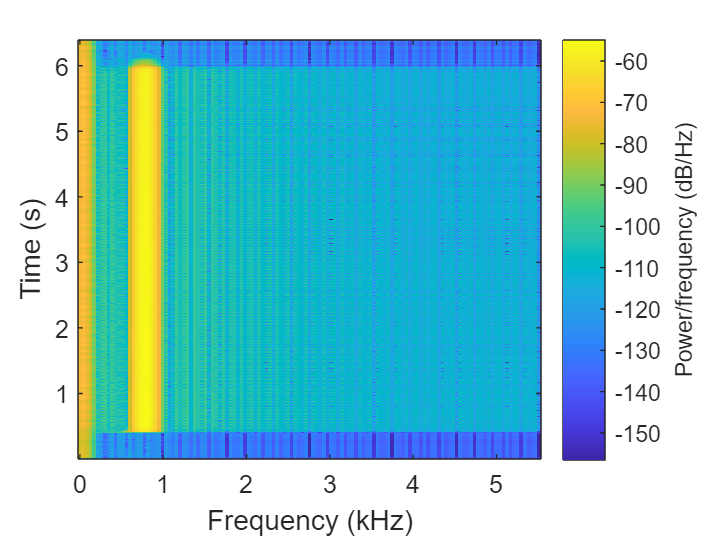

b3 = fir1(99,1800/fs,"low",hamming(100));
y3 = filter(b3,1,y);
spectrogram(y3,hamming(100),10,256,fs)

audiowrite("written.wav",y3,fs)